# Basic Reservoirs

This notebook covers the basic functionalities of building reservoirs using structured grids, where the elements that compose the reservoir have the same shape and size. In the .mlx file, there are controls that allow the modification of the various reservoirs in the notebook. 

clear;

## Rectangular grid

A retangular grid is the most simple grid available in MRST, where the definition is based on the number of rectangular cells along the three cartesian axes. 

The following code shows the definition of the number of cells in the X, Y and Z axes, and the determination of the length of each side of the rectangular domain, in m.

num_cell_x = 40;
num_cell_y = 40;
num_cell_z = 40;

len_x = 50;
len_y = 50;
len_z = 50;

Using the "cartGrid" function, we can generate the basic geometry G, while the function "computeGeometry" is necessary to compute other values of interest, such as cell and face centroids, normals, areas, and such. (Refer to the computeGeometry.m function for more information)

G = cartGrid([num_cell_x, num_cell_y, num_cell_z], [len_x, len_y, len_z]);
G = computeGeometry(G);

With a grid defined, we can plot it. Some of the plot definitions are shown in the following code, such as edge and face alpha values, which vary from 0, which is transparent, to 1, which is solid. Colors of the faces and grids can also be defined using color names.

edge_alpha = 0.5;
face_alpha = 0.3;
edge_color = "black";
face_color = "blue";

To plot the grid, we use the function "plotGrid". We can use "view(3)" for an isometric view, but this can be modified for different views, using different parameters. "axis equal" is useful to set a proportional grid.

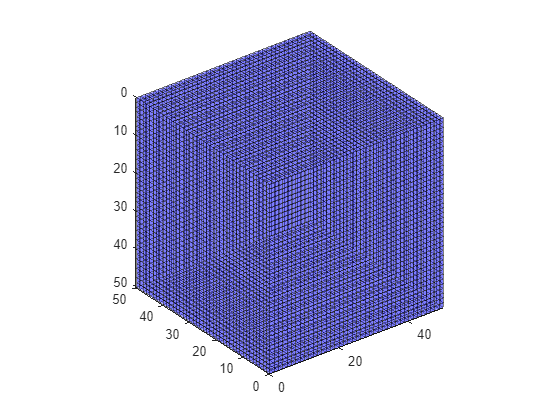

clf;
plotGrid(G,'EdgeAlpha', edge_alpha, 'FaceAlpha', face_alpha, 'EdgeColor', edge_color, 'FaceColor', face_color);
view(3);
axis equal;

## Spherical grid

To define grids with various shapes, we can start with a rectangular grid, and remove cells based on a given criteria, such as the desired radius for a spherical grid. First, we must identify the smallest cartesian length, which will be the upper bound for our spherical grid.

radius = 12;

To remove the cells, we use the cell centroids, and pass the to the sphere formula, centered at the middle of the domain.


$$r^2 ={\left(x-\frac{X}{2}\right)}^2 +{\left(y-\frac{Y}{2}\right)}^2 +{\left(z-\frac{Z}{2}\right)}^2$$


where, x, y, z, are the coordinates fo each centroid in the cartesian plane, X, Y, Z, the length of each axes in the cartesian domain. With the effective radius of all cells, we compare to our desired radius and this comparison results in a bool vector, which has the cells to be removed, that is then passed to the "removeCells" function.

c = G.cells.centroids;
criteria = sqrt((c(:,1) - (len_x/2)).^2 + (c(:,2) - (len_y/2)).^2 + (c(:,3) - (len_z/2)).^2);
G_sphere = removeCells(G, criteria>radius);
G_sphere = computeGeometry(G_sphere);

In this case, to plot this grid, we first plot the rectangular grid with transparent faces, for reference, then we plot the spherical grid.

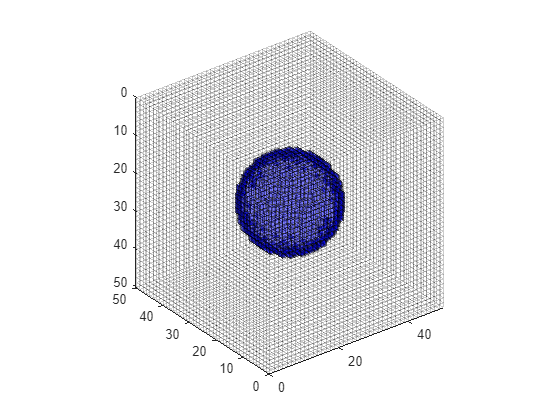

clf;
plotGrid(G,'EdgeAlpha', 0.2, 'FaceAlpha', 0)
plotGrid(G_sphere,'EdgeAlpha', edge_alpha, 'FaceAlpha', face_alpha, 'EdgeColor', edge_color, 'FaceColor', face_color)
view(3)
axis equal

## Ellipsoid grid

We can use a similar approach to make ellipsoid reservoirs, with the addition of three parameters that shrink the sphere in the three directions.

radius = 12;
shrink_x =2;
shrink_y =1;
shrink_z =0.5;

We use the same procedure to remove the cells, same as before, but each component is multiplied by the shrink factor. If the factor is less than 1, it streches the sphere, other wise, it shrinks the sphere.

c = G.cells.centroids;
criteria = sqrt(shrink_x*(c(:,1) - (len_x/2)).^2 + shrink_y*(c(:,2) - (len_y/2)).^2 + shrink_z*(c(:,3) - (len_z/2)).^2);
G_ellipsoid = removeCells(G, criteria>radius);
G_ellipsoid = computeGeometry(G_ellipsoid);

Same plot as before, but the sphere is also present to illustrate the distortion obtained by this approach.

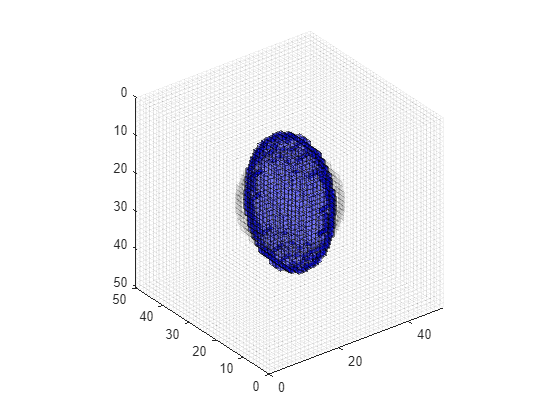

clf;
plotGrid(G,'EdgeAlpha', 0.05, 'FaceAlpha', 0)
plotGrid(G_sphere,'EdgeAlpha', 0.1, 'FaceAlpha', 0)
plotGrid(G_ellipsoid,'EdgeAlpha', edge_alpha, 'FaceAlpha', face_alpha, 'EdgeColor', edge_color, 'FaceColor', face_color)
view(3)
axis equal

## Parabolic Intersection

We can also use functions such that $z=f\left(x,y\right)$ to establish boundaries and use these boundaries to create different systems. One such exemple is of the 2-D parabolic function:


$$z={a*\left(x-\frac{X}{2}\right)}^2 +{b*\left(y-\frac{Y}{2}\right)}^2$$


such that:


$$z=f\left(\frac{X}{2},0\right)=f\left(\frac{X}{2},Y\right)=f\left(0,\frac{Y}{2}\right)=f\left(X,\frac{Y}{2}\right)=0$$


Therefore:


$$z=\left(4\ldotp \frac{Z}{X^2 }\right)*{\left(x-\frac{X}{2}\right)}^2 +\left(4\ldotp \frac{Z}{Y^2 }\right)*{\left(y-\frac{Y}{2}\right)}^2$$


This function defines the uppermost boundary, and we can include a parameter to create a lower boundary by setting a vertical distance between the points.

topside_dist = 30;

c = G.cells.centroids;
criteria = c(:,3) - ((4*len_z/(len_x^2))*((c(:,1) - len_x/2).^2)+(4*len_z/(len_y^2))*((c(:,2) - len_y/2).^2));
G_parabolic = removeCells(G, criteria<0);

c = G_parabolic.cells.centroids;
criteria = c(:,3) - ((4*len_z/(len_x^2))*((c(:,1) - len_x/2).^2)+(4*len_z/(len_y^2))*((c(:,2) - len_y/2).^2));
G_parabolic = removeCells(G_parabolic, criteria>topside_dist);

Then we plot the system, including the original grid as reference

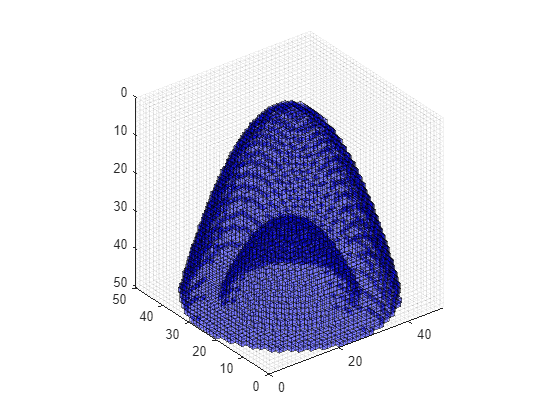

clf;
plotGrid(G,'EdgeAlpha', 0.05, 'FaceAlpha', 0)
plotGrid(G_parabolic,'EdgeAlpha', edge_alpha, 'FaceAlpha', face_alpha, 'EdgeColor', edge_color, 'FaceColor', face_color)
view(3)
axis equal

## Normal Intersection

Another function we can use is the normal distribution function defined as:


$$z=Z-Z*e^{-\left({\left(\frac{x-\frac{X}{2}}{d}\right)}^2 +{\left(\frac{y-\frac{Y}{2}}{d}\right)}^2 \right)}$$


In this scenario, the parameter d serves as a scaling factor for the distribution "skirt", where larger values result in broader distributions.

d = 20;
topside_dist = 15;
c = G.cells.centroids;
criteria = c(:,3) - (len_z - len_z*exp(-((c(:,1) - (len_x/2))./d).^2 - ((c(:,2) - (len_y/2))./d).^2));
G_normal = removeCells(G, criteria<0);
c = G_normal.cells.centroids;
criteria = c(:,3) - (len_z - len_z*exp(-((c(:,1) - (len_x/2))./d).^2 - ((c(:,2) - (len_y/2))./d).^2));
G_normal = removeCells(G_normal, criteria>topside_dist);

Then we plot the system, including the original grid as reference

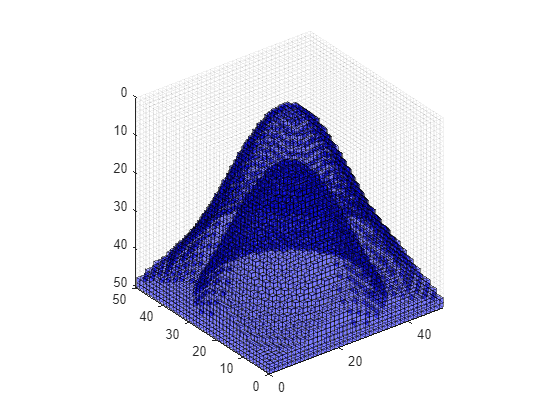

clf;
plotGrid(G,'EdgeAlpha', 0.05, 'FaceAlpha', 0)
plotGrid(G_normal,'EdgeAlpha', edge_alpha, 'FaceAlpha', face_alpha, 'EdgeColor', edge_color, 'FaceColor', face_color)
view(3)
axis equal

## Rectilinear Reservoirs

Using the tensorGrid function, we can create ortogonal reservoirs, where the different cells can have different dimensions, thus allowing different configurations.

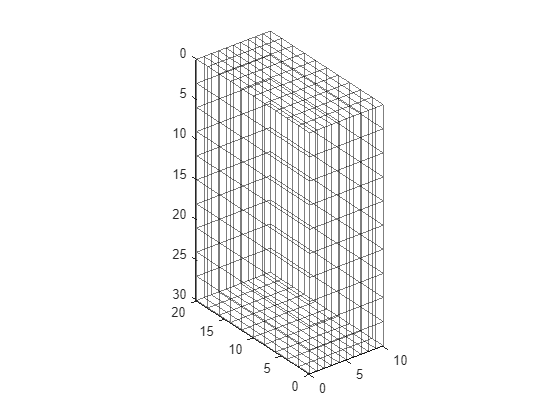

x = 0:1:10;
y = 0:1:10;
z = 0:1:10;

G = tensorGrid(x, 2.*y, 3.*z);

clf;
plotGrid(G,'EdgeAlpha', 0.5, 'FaceAlpha', 0)
view(3)
axis equal

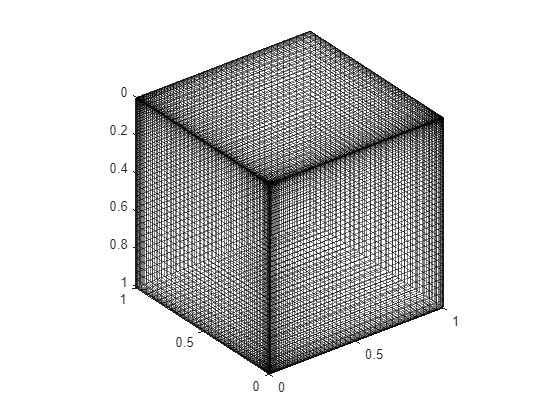

x = 0:0.02:1;
y = 0:0.02:1;
z = 0:0.02:1;
G = tensorGrid(x.^2, y.^2, z.^2);

clf;
plotGrid(G,'EdgeAlpha', 0.5, 'FaceAlpha', 0)
view(3)
axis equal

## Corner-point Reservoirs

A corner-point grid consists of a set of hexahedral cells that are topologically aligned in a Cartesian fashion so that the cells can be numbered using a logical ijk index. In its simplest form, a corner-point grid is specified in terms of a set of vertical or inclined pillars defined over an areal Cartesian 2D mesh in the lateral direction.

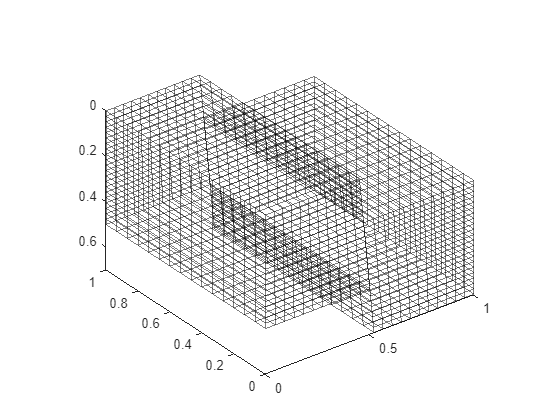

a = 22;
b = 15;
c = 21;
delta = .2;

grdecl = simpleGrdecl([a, b, c], delta, 'flat', true);
G = processGRDECL(grdecl);

clf;
plotGrid(G,'EdgeAlpha', 0.5, 'FaceAlpha', 0)
view(3)
axis equal

## Horizon-based Reservoirs

This is a more accurate approach to using functions to define reservoir surfaces. 

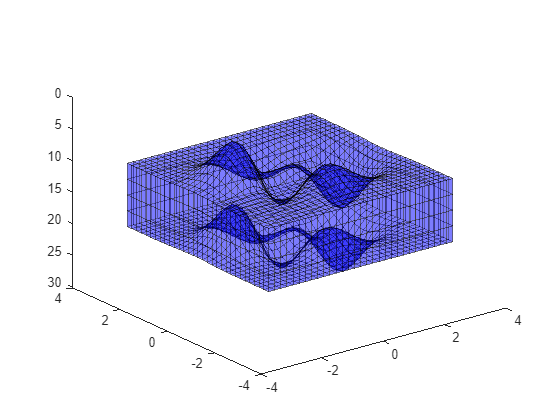

thickness = 10;
number_of_layers = 4;

[y,x,z] = peaks(30); z = z + thickness;
horizons = {struct('x',x,'y',y,'z',z),struct('x',x,'y',y,'z',z + thickness)};
grdecl = convertHorizonsToGrid(horizons,'layers', number_of_layers);
G = processGRDECL(grdecl);

clf;
plotGrid(G,'EdgeAlpha', edge_alpha, 'FaceAlpha', face_alpha, 'EdgeColor', edge_color, 'FaceColor', face_color)
view(3)

Now, let's examine the necessary steps: first, define the domain in x and y

len = 4;
num_cell = 30;
range = -(len/2):(len/num_cell):(len/2);
x = range';
y = range;
for i = 1:(length(range) - 1)
    x = [x range'];
    y = [y; range];
end

Define the function:

thickness = 10;
number_of_layers = 4;
nd = 30;

z = zeros(length(range));

for i = 1:(length(range))
    for j = 1:(length(range))
        z(i, j) = -nd*exp(-(x(i, j)^2 + y(i, j)^2));
    end
end

horizons = {struct('x',x,'y',y,'z',z),struct('x',x,'y',y,'z',z + thickness)};
grdecl = convertHorizonsToGrid(horizons,'layers', number_of_layers);
G = processGRDECL(grdecl);

Plot:

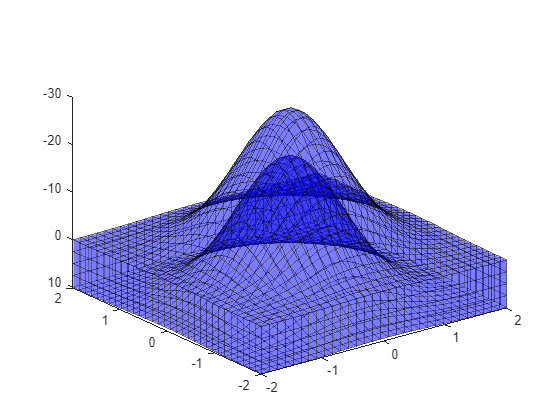

clf;
plotGrid(G,'EdgeAlpha', edge_alpha, 'FaceAlpha', face_alpha, 'EdgeColor', edge_color, 'FaceColor', face_color)
view(3)

Another example:

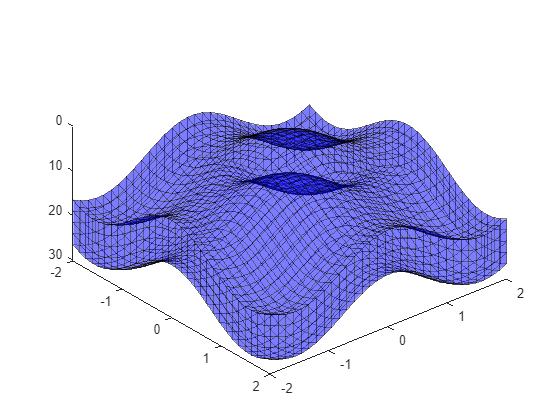

len = 4;
num_cell = 30;
range = -(len/2):(len/num_cell):(len/2);
x = range';
y = range;
for i = 1:(length(range) - 1)
    x = [x range'];
    y = [y; range];
end

thickness = 10;
number_of_layers = 4;
nd = 10;

z = zeros(length(range));

for i = 1:(length(range))
    for j = 1:(length(range))
        z(i, j) = nd*(sin(x(i, j))^2 + sin(y(i, j))^2);
    end
end

horizons = {struct('x',x,'y',y,'z',z),struct('x',x,'y',y,'z',z + thickness)};
grdecl = convertHorizonsToGrid(horizons,'layers', number_of_layers);
G = processGRDECL(grdecl);

clf;
plotGrid(G,'EdgeAlpha', edge_alpha, 'FaceAlpha', face_alpha, 'EdgeColor', edge_color, 'FaceColor', face_color)
view(3)